clc, clear, close all
format short g

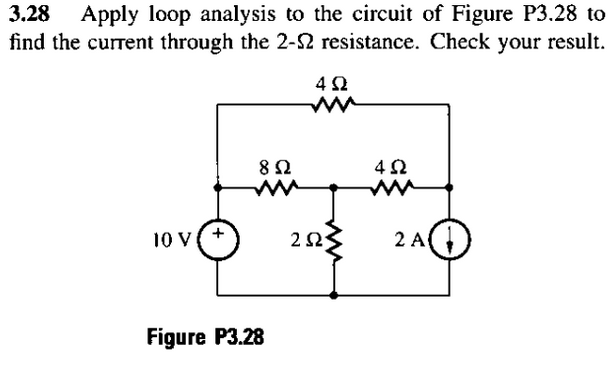

Redibujamos el circuito de acuerdo con el enunciado

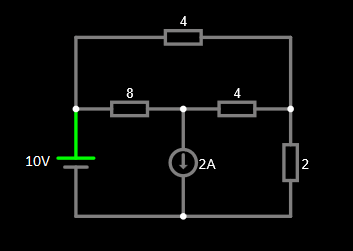

Dice que hay que hacer una analisis de mallas para encontrar la correinte en la resistencia de 2 ohm, por lo que trazamos las lineas de correinte de malla, como el metodo de mallas utiliza la LTK, donde se trabaja con tensiones, vemos que en la fuente de corriente de 2A no se puede determinar su tension como funcion de una correinte y una resistencia, por lo que tenemos que trazar una super malla, de la siguiente manera:

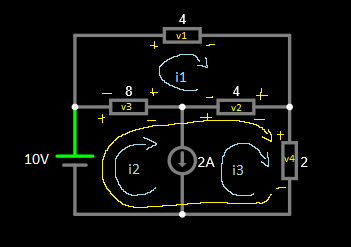

primero definimos las ecuaciones mara la **malla i1** en cada elemento:

syms i1 i2 i3

Vf = 10;
If = 2;

m_i1 = simplify((4*i1)+(4*(i1-i3))+(8*(i1-i2))==0); %ecuacion de malla i1

para la ecuacion de super malla primero definimos su ecuacion de restriccion que relaciona las corriente de la fuente de correinte con las mallas i2 e i3

ec_restric = (i2==If+i3) %ecuacion de restriccion

$$ec\_restric = i_{2}=i_{3}+2$$


sm_i2_i3 = simplify(-Vf+(8*(i2-i1))+(4*(i3-i1))+2*i3 == 0); %ecuacion de super malla i2 e i3

ya que tenemos las dos ecuaciones, podemos resolver el sistema 2x2 reemplazando la ecuacion de restriccion en las dos ecuaciones

m_i1 = simplify((4*i1)+(4*(i1-i3))+(8*(i1-(If+i3)))==0)

$$m\_i1 = 4\,i_{1}=3\,i_{3}+4$$

sm_i2_i3 = simplify(-Vf+(8*((If+i3)-i1))+(4*(i3-i1))+2*i3 == 0)

$$sm\_i2\_i3 = 6\,i_{1}=7\,i_{3}+3$$

m = [4 -3;6 -7];
n = [4;3];
h = m\n;
i1 = h(1,1)

i1 =           1.9


i3 = h(2,1)

i3 =           1.2


i2 = i3 + 2

i2 =           3.2


Ya que tenemos la correinte en cada malla odemos decir que **la corriente que atraviera la resistencia de 2 ohm, es i3, o sea 1.2 A. **Lo verificamos en el simulador: